SIGNALS & SYSTEMS - LAB 10

Name: SYED SUALEH ABBAS  ID: 10303

% TASK 1:
clc; clear; close all;

ftable = [1;2;3;4;5]*[80,110];   % Frequency table
fs = 8000;
xx = [];

keys = rem(3:12,10) + 1;

for ii = 1:length(keys)
    kk = keys(ii);

    xx = [xx, zeros(1,400)];   % silence

    krow = ceil(kk/2);
    kcol = rem(kk-1,2) + 1;

    dur = 0.15;
    t = 0:1/fs:dur;

    xx = [xx, cos(2*pi*ftable(krow,kcol)*t)];
end

soundsc(xx,fs);

## **1. How the program generates a long signal using a frequency table**

The program uses a  frequency table (`ftable`) to store predefined frequency values. In each iteration of the loop, it selects one frequency from the table based on calculated rows and columns.

For every selected frequency, the program generates a cosine wave (a sinusoidal signal) of short duration. Before adding each tone, it inserts a short segment of zeros to create silence. These silence segments and cosine signal are then **joined together** into one long signal vector `xx`.

So overall, the program builds a long signal step by step by:

- picking a frequency from the table, 

- generating its corresponding sinusoidal waveform, 

- adding silence before it, 

- and appending everything to the existing signal. 

And then this process repeats for multiple frequencies, resulting in a continuous signal made of multiple tone bursts.

## **2. Determine the size of the table and all of its entries, and then state the playing order of the frequencies.**

Size of the table, its entries, and playing order

The frequency table is created as:

`ftable = [1;2;3;4;5]*[80,110]`

- The first vector is a **5×1 column vector**

- The second vector is a 1×2** row vector**

So the resulting table is 5×2 (5 rows, 2 columns)

**Playing order of frequencies:**

The index `kk` is generated using:

`keys = rem(3:12,10) + 1;`

Which gives:

`[4 5 6 7 8 9 10 1 2 3]`

For each `kk`, the program computes:

- row: `ceil(kk/2)`

- column: `rem(kk-1,2)+1`

This results in the following sequence of frequencies:

So the tones are played in this order.

## **3. Determine the total length of the signal played by the soundsc function. How many samples and how many seconds?**

Each loop iteration adds:

400 samples of silence**, then**plus a cosine signal of duration **0.15 seconds**

**So,**

- Sampling frequency fs=8000Hz

- Tone duration:0.15×=1200 samples 

- Total per iteration:400+1200=1600 samples 

- Number of iterations:10

Total samples: 1600 × 10 = 16000 samples

Total time: 16000 / 8000 = 2 seconds approx.

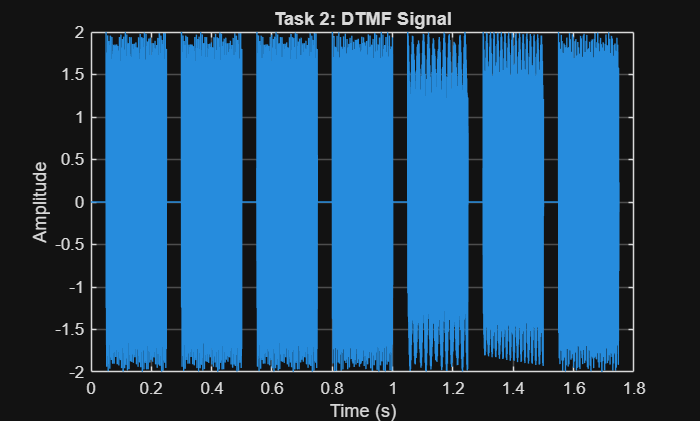

% TASK 2:
clc; clear; close all;

function xx = dtmfdial(keyNames, fs)

% DTMF keypad layout
dtmf.keys = ['1','2','3','A';
             '4','5','6','B';
             '7','8','9','C';
             '*','0','#','D'];

% Column frequencies (high tones)
dtmf.colTones = ones(4,1)*[1209,1336,1477,1633];

% Row frequencies (low tones)
dtmf.rowTones = [697;770;852;941]*ones(1,4);

% Setting the duration for each keytone
toneDur = 0.20;   % tone length
silDur  = 0.05;   % silence 

% time vector for one tone
tTone = 0:1/fs:toneDur-1/fs;

% addign silence blocks
silence = zeros(1, round(silDur*fs));

% final output signal is empty at start
xx = [];
for k = 1:length(keyNames)

    % finding row, column position
    [ii,jj] = find(keyNames(k) == dtmf.keys);

    % gettign row frequency and column frequency
    f1 = dtmf.rowTones(ii,jj);
    f2 = dtmf.colTones(ii,jj);

    % generating toen by summing both signals
    tone = cos(2*pi*f1*tTone) + cos(2*pi*f2*tTone);

    % addign silence
    xx = [xx silence tone];
end

end

% TESTING
fs = 8000;   % sampling frequency
xx = dtmfdial('5551234', fs);
soundsc(xx, fs);
t = (0:length(xx)-1)/fs;
figure;

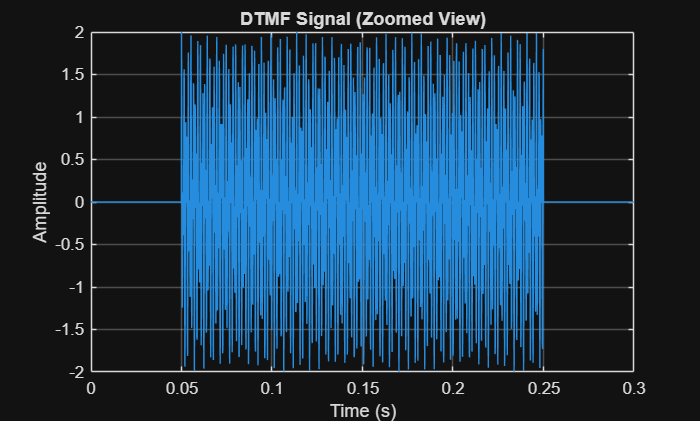

plot(t, xx);
title('Task 2: DTMF Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

samples = fs * 0.3;   % first 0.3 seconds

figure;

plot(t(1:samples), xx(1:samples));
title('DTMF Signal (Zoomed View)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% TASK 3
function beta = maxbeta(L, fb, fs)

n = 0:L-1;

% unscaled FIR bandpass filter
h = cos(2*pi*fb*n/fs);

% frequency response
[H, w] = freqz(h, 1, 1024);

% find peak magnitude
peak = max(abs(H));

% scaling factor so peak becomes 1
beta = 1/peak;

end

% test case
L = 51;
fb = 852;

Beta value:


fs = 8000;

    0.0394



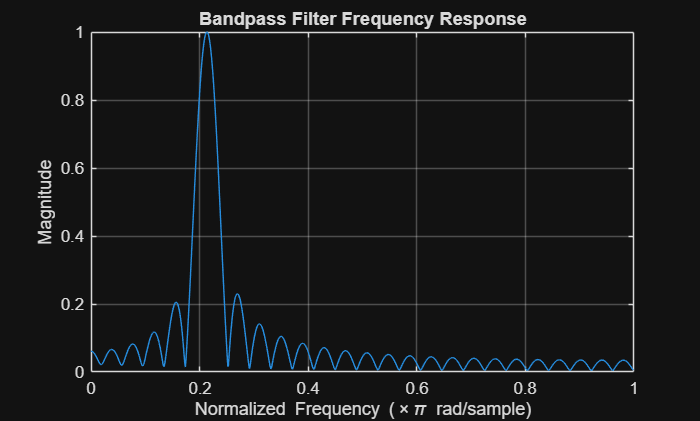


beta = maxbeta(L, fb, fs);

disp('Beta value:');
disp(beta);
% scaled impulse response
n = 0:L-1;

h = beta * cos(2*pi*fb*n/fs);

% plotting the frequency response
[H,w] = freqz(h,1,1024);

figure;

plot(w/pi, abs(H));
title('Bandpass Filter Frequency Response');
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

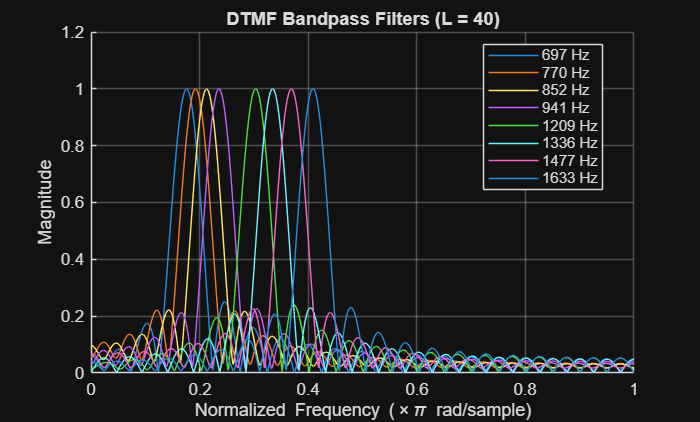

% TASK 4:
function hh = dtmfdesign(fcent, L, fs)

% number of frequencies (8 DTMF tones)
N = length(fcent);

% initialize filter matrix (L rows, 8 columns)
hh = zeros(L, N);

% loop over each center frequency
for k = 1:N

    % time index for FIR filter
    n = 0:L-1;

    % basic cosine bandpass filter, not scaled
    h = cos(2*pi*fcent(k)*n/fs);

    % find scaling factor
    beta = maxbeta(L, fcent(k), fs);

    % apply scaling so peak response = 1
    h = beta * h;

    % store in kth column
    hh(:,k) = h;

end

end

% Now will do L=40 test and frequency response:

fs = 8000;
L = 40;

fcent = [697 770 852 941 1209 1336 1477 1633];

hh = dtmfdesign(fcent, L, fs);

w = linspace(0, pi, 1024);

figure;
hold on;

legendNames = strings(1,8);

for k = 1:8
    H = freqz(hh(:,k), 1, w);
    plot(w/pi, abs(H));

    % store legend text
    legendNames(k) = string(fcent(k)) + " Hz";
end

title('DTMF Bandpass Filters (L = 40)');

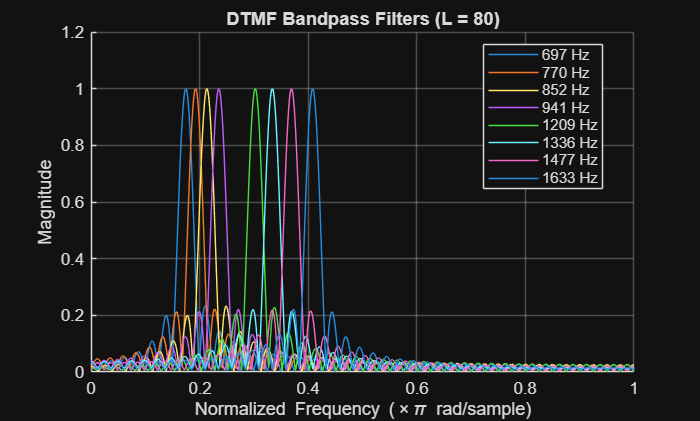

xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

legend(legendNames, 'Location', 'best');

% Now we will do L= 80 and comparison:
L = 80;

hh = dtmfdesign(fcent, L, fs);

figure;
hold on;

legendNames = strings(1,8);

for k = 1:8
    H = freqz(hh(:,k), 1, w);
    plot(w/pi, abs(H));

    legendNames(k) = string(fcent(k)) + " Hz";
end

title('DTMF Bandpass Filters (L = 80)');

xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude');
grid on;

legend(legendNames, 'Location', 'best');

## **4. EFFECTS OF FILTERING LENGTH L ON PASSBAND WIDTH:**

The passband width of an FIR bandpass filter is **inversely related to the filter length **L. This means that when the filter length increases, the main lobe of the frequency response becomes less or narrow.

In the comparison between L=40 and L=80, this behavior is clearly observed. For L=40, the frequency responses are relatively wider, meaning each filter allows a broader range of frequencies to pass. As a result, there is more overlap between adjacent DTMF frequency bands. This can cause interference between neighboring tones.

When L=80, the filters become much sharper and more selective. The main lobes become narrower, and the transition between passband and stopband becomes more abrupt. This reduces overlap between adjacent frequencies and improves frequency discrimination.

Therefore, the statement is **true**: increasing LLL reduces passband width and improves selectivity.

## 5. Selectivity of the bandpass filters

The bandpass filters in the DTMF system are designed to isolate specific sinusoidal components corresponding to the standard DTMF frequencies. Each filter ideally passes only one frequency while attenuating all others.

From the frequency response plots, it can be seen that each filter has a peak at its center frequency and much lower response at other frequencies. However, since the filters are not perfectly ideal, some overlap still exists between nearby frequency bands, especially when L is small (such as L=40).

For larger L, the filters become more selective, meaning they better isolate a single frequency component and decrease others. In this case, most filters are narrow enough to separate the DTMF tones effectively.

However, the separation is not equally easy for all frequencies. The closest spaced frequencies in the DTMF set are more difficult to isolate.

The most challenging filter design occurs in row tones. These frequencies are relatively close compared to others, so their frequency responses tend to overlap more. This makes it harder for a single filter length L to fully separate them without interference. For example: 852 Hz and 941 Hz

% Task 5:
function sc = dtmfscore(xx, hh)

% Normalize input signal
xx = xx * (2 / max(abs(xx)));

% Filter
y = conv(xx, hh);

% Peak detection
peakValue = max(abs(y));

% Decision rule
if peakValue >= 0.59
    sc = 1;
else
    sc = 0;
end

end

fs = 8000;

% generating signal for key 5
one_key = '5';
xx1 = dtmfdial(one_key, fs);

% extracting tone segments
[nstart1, nstop1] = dtmfcut(xx1, fs);
x_seg1 = xx1(nstart1(1):nstop1(1));

% filter bank
fcent = [697 770 852 941 1209 1336 1477 1633];
hh80 = dtmfdesign(fcent, 80, fs);

% scoring
scores1 = zeros(1,8);

for i = 1:8
    scores1(i) = dtmfscore(x_seg1, hh80(:,i));
end


Filter 1 (697 Hz): score = 0
Filter 2 (770 Hz): score = 1
Filter 3 (852 Hz): score = 0
Filter 4 (941 Hz): score = 0
Filter 5 (1209 Hz): score = 0
Filter 6 (1336 Hz): score = 1
Filter 7 (1477 Hz): score = 0
Filter 8 (1633 Hz): score = 0


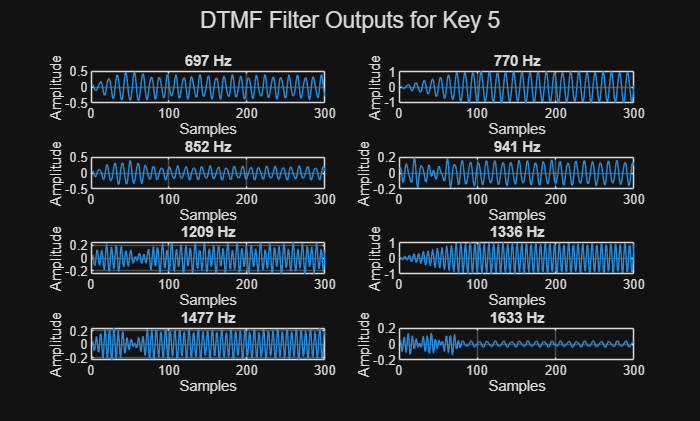

%printing results
for i = 1:8
    fprintf('Filter %d (%d Hz): score = %d\n', i, fcent(i), scores1(i));
end
% PLOT SECTION 
figure;

for i = 1:8
    y = conv(x_seg1, hh80(:,i));

    subplot(4,2,i);
    plot(y(1:300));  
    grid on;

    title([num2str(fcent(i)) ' Hz']);
    xlabel('Samples');

    ylabel('Amplitude');
end

sgtitle('DTMF Filter Outputs for Key 5');

## **4. Why the filter must be scaled so that max |H(e^{jω})| = 1**

The scoring method in DTMF decoding is based on comparing the output amplitude of each bandpass filter. For this comparison to make sense, all filters must behave consistently in terms of gain.

If a bandpass filter is not normalized, it might unintentionally amplify the input signal depending on its design. That means one filter could give a large output simply because it has higher gain, not because the correct frequency is present. Another filter might give a small output even if the correct frequency is present, just because its gain is lower.

By forcing the frequency response magnitude to have a **maximum value of 1**, we ensure that every filter passes its target frequency without amplification or extra scaling. This makes the output amplitude directly dependent on the input signal strength, not on the filter design.

Since each DTMF tone consists of two sinusoids with known amplitude (after normalization), the output of a correctly tuned filter becomes predictable. If a frequency is present, the filter outputs a sinusoid with amplitude close to the expected value. If it is not present, the output remains small. This consistency is what makes the threshold (like 0.59) meaningful and reliable.

## **5. Why plotting the filtered output helps in debugging**

When we plot the first 200–500 samples of the filtered output, we can visually check how each bandpass filter reacts to the signal.

There are two clear cases:

- **Matched frequency (correct filter):**The output shows a strong sinusoidal waveform with noticeable amplitude. This happens because the filter is centered at a frequency that exists in the DTMF tone, so it passes it with minimal attenuation. 

- **Mismatched frequency (wrong filter):**The output is very small or nearly flat. This happens because the filter is rejecting that frequency, so only weak noise components appear. 

This visual check is useful because it confirms whether the filter bank is correctly designed, the frequency separation is working properly , and if the scoring threshold is reasonable or not. 

%TASK 6:
function keys = dtmfrun(xx, L, fs)


% DTMF keypad layout
dtmf.keys = ['1','2','3','A';
             '4','5','6','B';
             '7','8','9','C';
             '*','0','#','D'];

dtmf.colTones = ones(4,1)*[1209,1336,1477,1633];
dtmf.rowTones = [697;770;852;941]*ones(1,4);


% All 8 center frequencies
center_freqs = [697 770 852 941 1209 1336 1477 1633];

% Designing filter bank
hh = dtmfdesign(center_freqs, L, fs);

% Finding the  tone segments
[nstart,nstop] = dtmfcut(xx, fs);

keys = [];   % output


% Loop has to go over each detected tone

for kk = 1:length(nstart)

    % extracting the one DTMF segment
    x_seg = xx(nstart(kk):nstop(kk));

    % scoring all 8 filters
    score = zeros(1,8);

    for i = 1:8
        score(i) = dtmfscore(x_seg, hh(:,i));
    end

    % finding row tones and column tones
    row_idx = find(score(1:4));     % first 4 are row frequencies
    col_idx = find(score(5:8)) + 4; % last 4 are column frequencies

    % safety check
    if length(row_idx)==1 && length(col_idx)==1

        % map row/col to key
        key = dtmf.keys(row_idx, col_idx-4);
        keys = [keys key];  % concatenate result

    else
        keys = [keys '?']; % unknown detection
    end
end

end

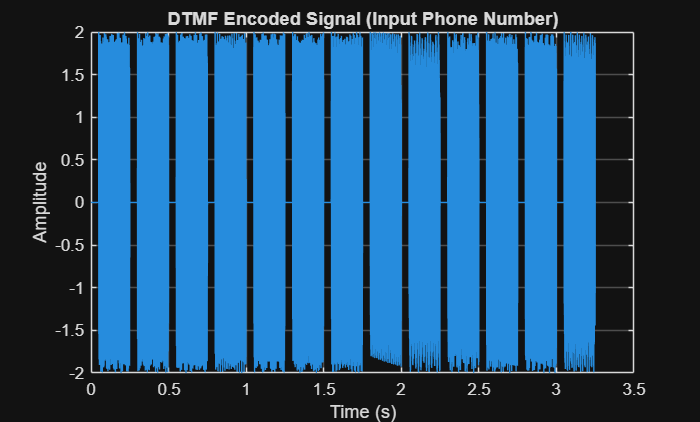

% Task 7: Full system test

clc;
clear;

fs = 8000;   % sampling frequency, we will keep it constant for full system. 


% Input phone number, this is provided in lab manual
phoneNumber = '407*89132BADC';


% generating DTMF signal
xx = dtmfdial(phoneNumber, fs);

% Playing the generated signal
soundsc(xx, fs);

% Ploting  full signal just to see structure
t = (0:length(xx)-1)/fs;

figure;
plot(t, xx);
title('DTMF Encoded Signal (Input Phone Number)');

xlabel('Time (s)');
ylabel('Amplitude');
grid on;

%decoding signal
L = 80;   % filter length

decoded_keys = dtmfrun(xx, L, fs);

Decoded Keys:


407*89132BADC


%displaying  result
disp('Decoded Keys:');
disp(decoded_keys);